# Tarefa 01 - Algoritmo de Mantenga/Voo de Lévy

## DISCIPLINA: Otimização Bioinspirada

### **Professores: **Jasmine Araújo e Glauco Gonçalves

### **Aluno: **Heictor Costa

close all
clear all
clc

Defina o número de passos (*n*)

n = 200; %number of steps

Defina o número de Dimensões (*m*)

m = 2;  % m     -> Number of Dimensions 

Defina o valor do parâmetro Beta (*beta*)

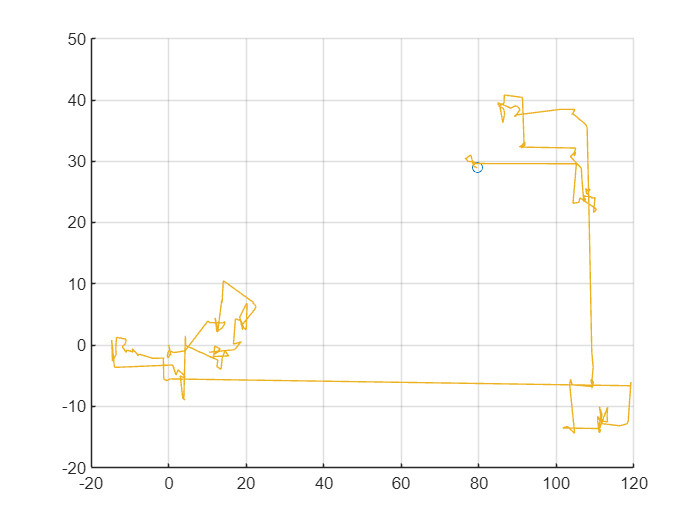

beta = 1.4;        % beta  -> Power law index  % Note: 1 < beta < 2

 
[x,y,z] = deal(zeros(n,3));
figure(1)
hold on

d = levy(n,m,beta); % generate the steps 
h = animatedline;
l = 1:10;

if m==2
    for i = 2:length(d) % use those steps 
        x(i)= x(i-1)+d(i,1);
        y(i)= y(i-1)+d(i,2);
    end
    
    comet(x(:,1),y(:,1));
elseif m==3
    for i = 2:length(d) % use those steps 
        x(i)= x(i-1)+d(i,1);
        y(i)= y(i-1)+d(i,2);
        z(i)= z(i-1)+d(i,3);
    end

    comet3(x(:,1),y(:,1),z(:,1));    
end    

grid on
hold off

## Análise do Algoritmo:

Ao analisar as mudanças de valores do parâmetro Beta, é possível identificar que o mesmo interfere na distribuição de passeios longos, ao longo da execução do algoritmo.

Essa interferência é claramente perceptível ao compara os valores dos eixos de duas execuções, com valores de Beta distintos, como ilustrado a seguir:

### Figura 2: Betha = 1

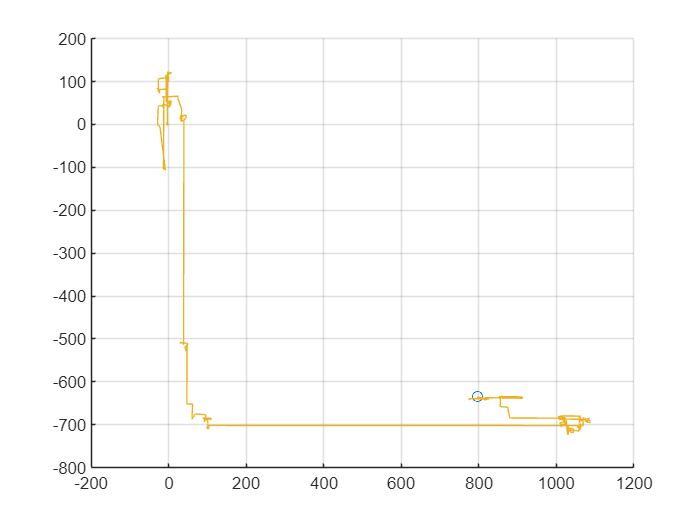

 
close all
clear all
clc

[x,y,z] = deal(zeros(400,3));
figure(2)
hold on

d = levy(400,2,1); % generate the steps 
h = animatedline;
l = 1:10;


    for i = 2:length(d) % use those steps 
        x(i)= x(i-1)+d(i,1);
        y(i)= y(i-1)+d(i,2);
    end
    
    comet(x(:,1),y(:,1));


grid on
hold off

### Figura 2: Betha = 2

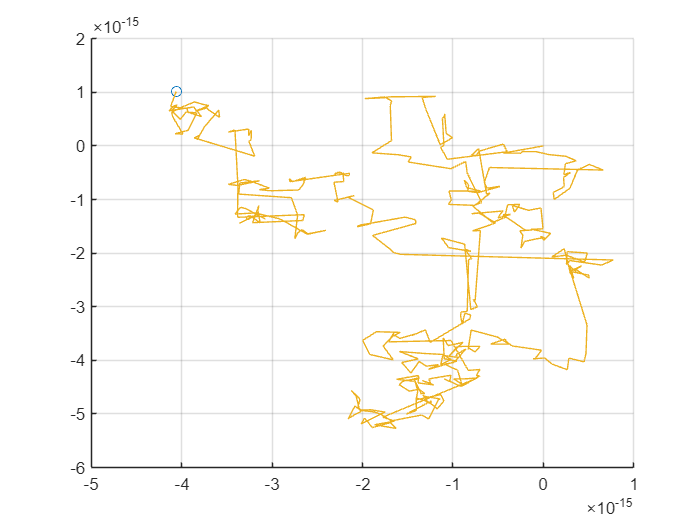

 
close all
clear all
clc
[x,y,z] = deal(zeros(400,3));
figure(3)
hold on

d = levy(400,2,2); % generate the steps 
h = animatedline;
l = 1:10;


    for i = 2:length(d) % use those steps 
        x(i)= x(i-1)+d(i,1);
        y(i)= y(i-1)+d(i,2);
    end
    
    comet(x(:,1),y(:,1));


grid on
hold off

function [z] = levy(n,m,beta)


    num = gamma(1+beta)*sin(pi*beta/2); % used for Numerator 
    
    den = gamma((1+beta)/2)*beta*2^((beta-1)/2); % used for Denominator

    sigma_u = (num/den)^(1/beta);% Standard deviation

    u = random('Normal',0,sigma_u^2,n,m); 
    
    v = random('Normal',0,1,n,m);

    z = u./(abs(v).^(1/beta));
    
     
end
